# Stoch Proc MM15

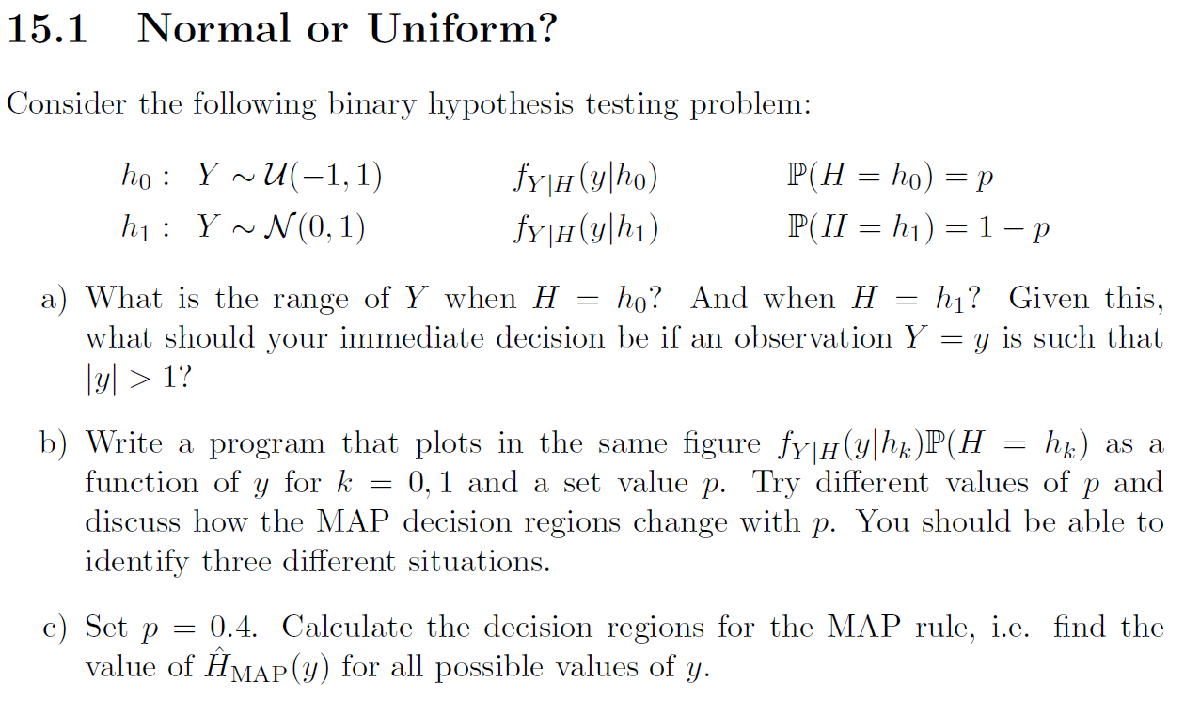

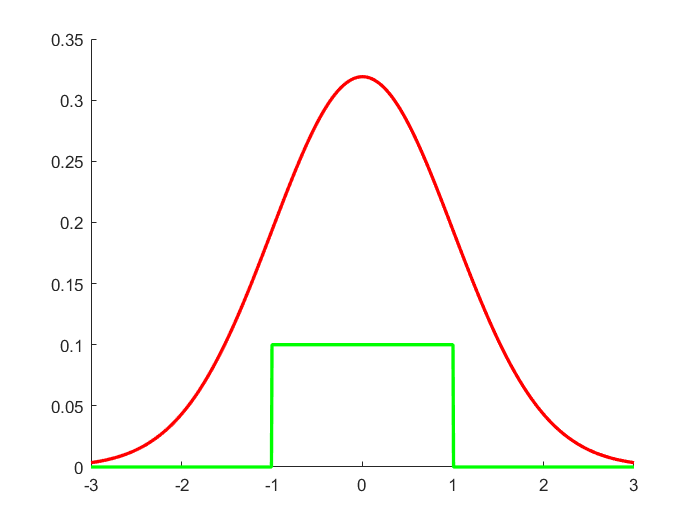

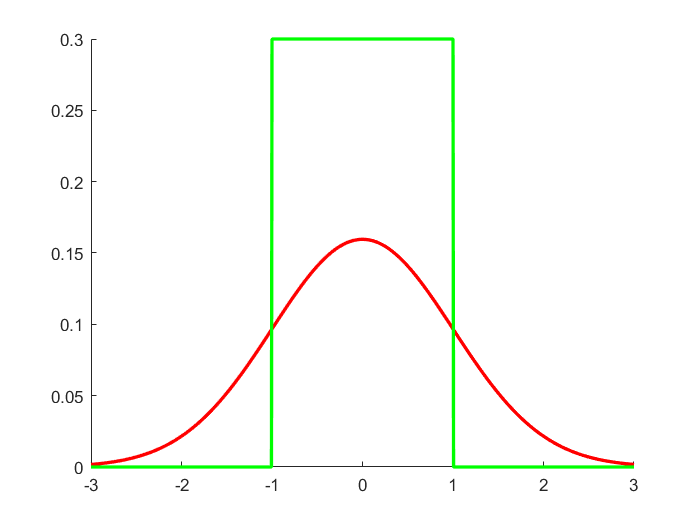

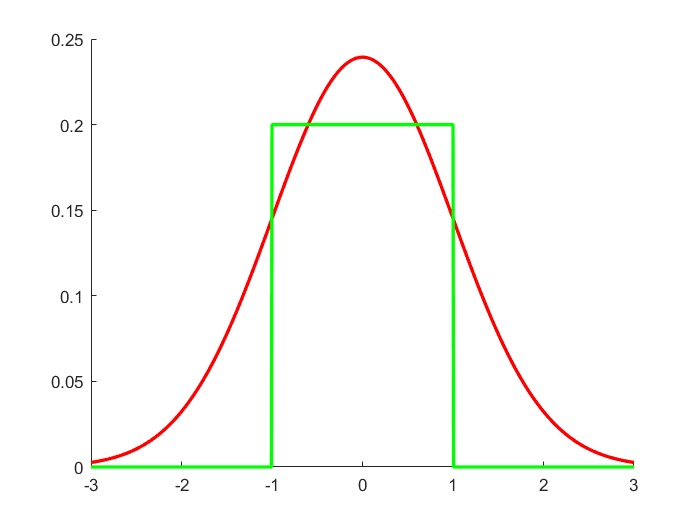

close all
N = 1000;
y_vals = linspace(-3,3,N);
mu = 0;
sigma = 1;
pd_normal = makedist('Normal','mu',mu,'sigma',sigma);
pd_uniform = makedist("Uniform","lower",-1,"upper",1);

p = [0.2 0.6 0.4];
for i = 1:3
    figure(i)
    hold on
    p_normal = plot(y_vals,pdf(pd_normal,y_vals)*(1-p(i)),'r', 'Linewidth',2);
    p_uniform = plot(y_vals,pdf(pd_uniform,y_vals)*p(i),'g', 'Linewidth',2);
end

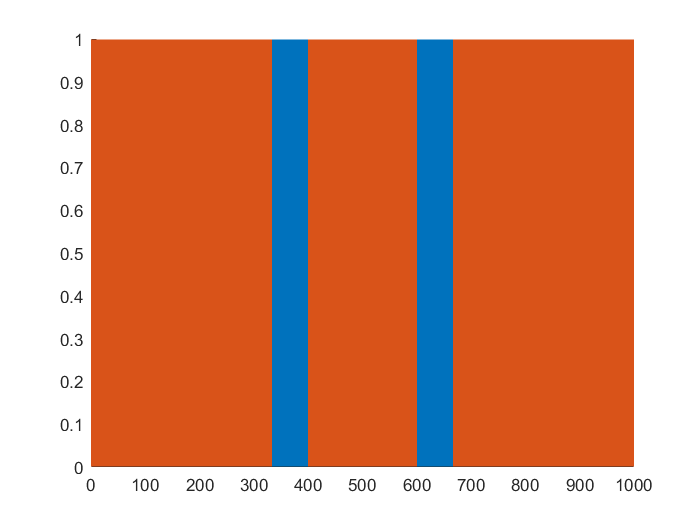


p = 0.4; 

% C. Find skæringspunkter mellem de to grafer. 
H1 = pdf(pd_normal,y_vals)*(1-p);
H0 = pdf(pd_uniform,y_vals)*p;

region_H0 = zeros(N,1);
region_H1 = zeros(N,1);

for i = 1:N
    if H1(i)>H0(i)
        region_H1(i) = 1;
    else
        region_H0(i) = 1;
    end

end

figure(5)
hold on
p_h0 = stem(region_H0);
set(p_h0, 'Marker', 'none');
p_h1 = stem(region_H1);
set(p_h1, 'Marker', 'none');

%% Opgave 2

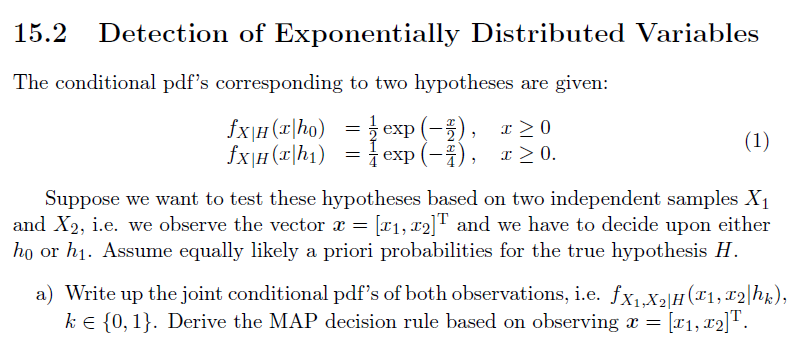

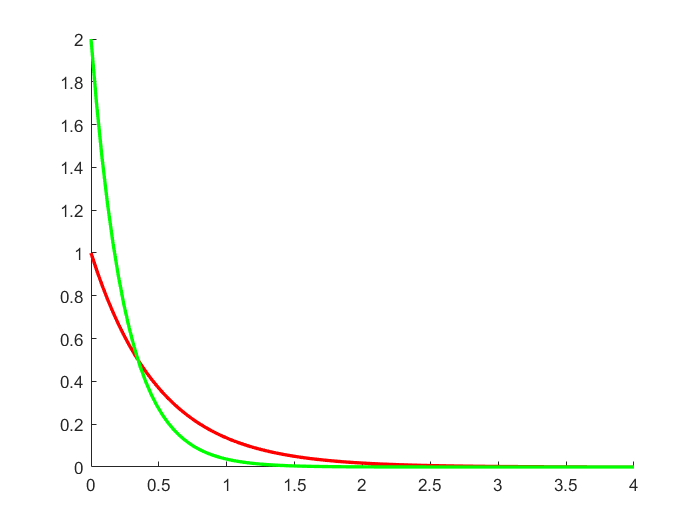

clear
N = 100;
p = 0.5;
range = linspace(0,4,N);
pd_h0 = makedist('Exponential',"mu",0.5);
pd_h1 = makedist("Exponential","mu",0.25);

H1 = pdf(pd_h1,range)*(1-p);
H0 = pdf(pd_h0,range)*p;

figure
hold on
p_H0 = plot(range,pdf(pd_h0,range)*(1-p),'r', 'Linewidth',2);
p_H1 = plot(range,pdf(pd_h1,range)*p,'g', 'Linewidth',2);